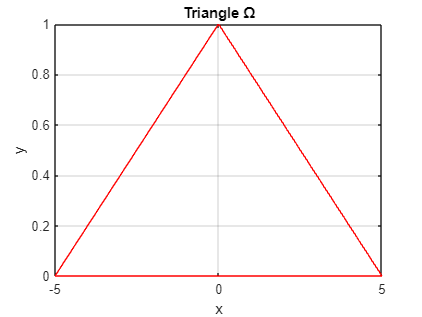

NOmega = 5; % Number of points on the triangle

% Generate the x and y coordinates of the triangle
x = [0, NOmega, -NOmega, 0];
y = [1, 0, 0, 1];

% Plot the triangle
plot(x, y, 'r-');
xlabel('x');
ylabel('y');
title('Triangle Ω');
grid on;

NOmega = 5; % Number of points on the triangle

% Generate the x and y coordinates of the triangle
x = [0, NOmega, -NOmega, 0];
y = [1, 0, 0, 1];

% Generate the time vector for the pulse
t = linspace(0, 2*pi, 100);

% Calculate the amplitude and frequency of the pulse
amp = 1;
freq = 1;

% Calculate the y values of the pulse
pulse = amp * (t >= 0 & t <= pi/2) + amp * (t > pi/2 & t <= pi) - amp * (t > pi & t <= 3*pi/2);

% Plot the triangular pulse
plot(t, pulse);
xlabel('Time');
ylabel('Amplitude');
title('Triangular Pulse');
grid on;

Error using DynamicSystem/step
Cannot simulate the time response of improper (non-causal) models.

Error in step (line 140)
   yout = step(sys,t);